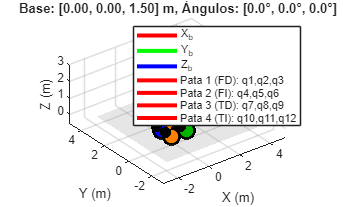

close all; clear all; clc



% Parámetros del robot cuadrúpedo
L0 = 0.2; % Offset vertical desde la base (altura del cubo)
L1 = 0.3; % Longitud primer eslabón
L2 = 0.5; % Longitud segundo eslabón
L3 = 0.5; % Longitud tercer eslabón
Lc = 1.0; % Longitud de la base (en X)
Lb = 0.8; % Ancho de la base (en Y)

%% Función para crear matriz DH estándar
function T = dh_standard(theta, d, a, alpha)
    T = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
         sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
         0, sin(alpha), cos(alpha), d;
         0, 0, 0, 1];
end

%% Función para matriz de rotación Euler ZYX
function R = euler_zyx(phi, theta, psi)
    % Roll (phi) - rotación alrededor de X
    Rx = [1, 0, 0;
          0, cos(phi), -sin(phi);
          0, sin(phi), cos(phi)];
    
    % Pitch (theta) - rotación alrededor de Y
    Ry = [cos(theta), 0, sin(theta);
          0, 1, 0;
          -sin(theta), 0, cos(theta)];
    
    % Yaw (psi) - rotación alrededor de Z
    Rz = [cos(psi), -sin(psi), 0;
          sin(psi), cos(psi), 0;
          0, 0, 1];
    
    R = Rz * Ry * Rx;
end

%% Función para dibujar un cubo (base del robot)
function draw_cube(T_wb, Lc, Lb, L0)
    % Vértices del cubo en el marco de la base
    vertices = [
         Lc/2,  Lb/2,  0;      % 1: superior frontal derecha
         Lc/2, -Lb/2,  0;      % 2: superior frontal izquierda
        -Lc/2, -Lb/2,  0;      % 3: superior trasera izquierda
        -Lc/2,  Lb/2,  0;      % 4: superior trasera derecha
         Lc/2,  Lb/2, -L0;     % 5: inferior frontal derecha
         Lc/2, -Lb/2, -L0;     % 6: inferior frontal izquierda
        -Lc/2, -Lb/2, -L0;     % 7: inferior trasera izquierda
        -Lc/2,  Lb/2, -L0      % 8: inferior trasera derecha
    ];
    
    % Transformar vértices al marco del mundo
    vertices_world = zeros(8, 3);
    for i = 1:8
        p = [vertices(i, :), 1]';
        p_w = T_wb * p;
        vertices_world(i, :) = p_w(1:3)';
    end
    
    % Definir las 6 caras del cubo
    faces = [
        1, 2, 6, 5;  % Cara frontal (X+)
        3, 4, 8, 7;  % Cara trasera (X-)
        1, 4, 8, 5;  % Cara derecha (Y+)
        2, 3, 7, 6;  % Cara izquierda (Y-)
        1, 2, 3, 4;  % Cara superior (Z = 0)
        5, 6, 7, 8   % Cara inferior (Z = -L0)
    ];
    
    % Dibujar el cubo con caras sólidas
    patch('Vertices', vertices_world, 'Faces', faces, ...
          'FaceColor', [0.7 0.7 0.7], 'FaceAlpha', 0.8, ...
          'EdgeColor', 'k', 'LineWidth', 2);
end

%% Función para calcular cinemática de una pata
function [P0, P1, P2, P3, Pf] = leg_kinematics(q1, q2, q3, Tb_0, L1, L2, L3)
    % Cinemática DH de la pata
    T0_1 = dh_standard(q1, 0, L1, -pi/2);
    T1_2 = dh_standard(q2, 0, L2, 0);
    T2_3 = dh_standard(q3, 0, L3, 0);
    T3_f = [0 0 -1 0; -1 0 0 0; 0 1 0 0; 0 0 0 1];
    
    % Posiciones de las articulaciones en el marco de la base
    P0 = Tb_0 * [0; 0; 0; 1];
    P1 = Tb_0 * T0_1 * [0; 0; 0; 1];
    P2 = Tb_0 * T0_1 * T1_2 * [0; 0; 0; 1];
    P3 = Tb_0 * T0_1 * T1_2 * T2_3 * [0; 0; 0; 1];
    Pf = Tb_0 * T0_1 * T1_2 * T2_3 * T3_f * [0; 0; 0; 1];
end

%% Función para dibujar el robot completo
function draw_quadruped(xb, yb, zb, phi, theta, psi, q_legs, L0, L1, L2, L3, Lc, Lb)
    % q_legs: matriz 4x3 con [q1, q2, q3] para cada pata
    % Pata 1: Frontal Derecha (q1, q2, q3)
    % Pata 2: Frontal Izquierda (q4, q5, q6)
    % Pata 3: Trasera Derecha (q7, q8, q9)
    % Pata 4: Trasera Izquierda (q10, q11, q12)
    
    clf; hold on; grid on; axis equal;
    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    view(3);
    
    % Transformación de la base flotante respecto al mundo
    R_b = euler_zyx(phi, theta, psi);
    T_wb = eye(4);
    T_wb(1:3, 1:3) = R_b;
    T_wb(1:3, 4) = [xb; yb; zb];
    
    % Dibujar la base como cubo sólido
    draw_cube(T_wb, Lc, Lb, L0);
    
    % Dibujar ejes de la base
    axis_length = 0.4;
    origin_base = T_wb * [0; 0; 0; 1];
    x_axis = T_wb * [axis_length; 0; 0; 1];
    y_axis = T_wb * [0; axis_length; 0; 1];
    z_axis = T_wb * [0; 0; axis_length; 1];
    
    plot3([origin_base(1), x_axis(1)], [origin_base(2), x_axis(2)], ...
          [origin_base(3), x_axis(3)], 'r-', 'LineWidth', 3); % X rojo
    plot3([origin_base(1), y_axis(1)], [origin_base(2), y_axis(2)], ...
          [origin_base(3), y_axis(3)], 'g-', 'LineWidth', 3); % Y verde
    plot3([origin_base(1), z_axis(1)], [origin_base(2), z_axis(2)], ...
          [origin_base(3), z_axis(3)], 'b-', 'LineWidth', 3); % Z azul
    
    % Transformaciones de la base a cada pata (Tb_0 para cada pata)
    Tb_0_legs = cell(4, 1);
    
    % Pata 1: Frontal Derecha (q1, q2, q3)
    Tb_0_legs{1} = [0 0 1 Lc/2; 0 1 0 Lb/2; -1 0 0 -L0; 0 0 0 1];
    
    % Pata 2: Frontal Izquierda (q4, q5, q6)
    Tb_0_legs{2} = [0 0 1 Lc/2; 0 1 0 -Lb/2; -1 0 0 -L0; 0 0 0 1];
    
    % Pata 3: Trasera Derecha (q7, q8, q9)
    Tb_0_legs{3} = [0 0 1 -Lc/2; 0 1 0 Lb/2; -1 0 0 -L0; 0 0 0 1];
    
    % Pata 4: Trasera Izquierda (q10, q11, q12)
    Tb_0_legs{4} = [0 0 1 -Lc/2; 0 1 0 -Lb/2; -1 0 0 -L0; 0 0 0 1];
    
    % Colores para cada pata
    colors = {[1 0 0], [0 0.7 0], [0 0 1], [1 0.5 0]}; % Rojo, Verde, Azul, Naranja
    leg_names = {'Pata 1 (FD): q1,q2,q3', 'Pata 2 (FI): q4,q5,q6', ...
                 'Pata 3 (TD): q7,q8,q9', 'Pata 4 (TI): q10,q11,q12'};
    
    % Dibujar cada pata
    for leg = 1:4
        q1 = q_legs(leg, 1);
        q2 = q_legs(leg, 2);
        q3 = q_legs(leg, 3);
        
        % Calcular cinemática de la pata
        [P0, P1, P2, P3, Pf] = leg_kinematics(q1, q2, q3, Tb_0_legs{leg}, L1, L2, L3);
        
        % Transformar al mundo
        P0_w = T_wb * P0;
        P1_w = T_wb * P1;
        P2_w = T_wb * P2;
        P3_w = T_wb * P3;
        Pf_w = T_wb * Pf;
        
        % Dibujar eslabones
        plot3([P0_w(1), P1_w(1)], [P0_w(2), P1_w(2)], [P0_w(3), P1_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        plot3([P1_w(1), P2_w(1)], [P1_w(2), P2_w(2)], [P1_w(3), P2_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        plot3([P2_w(1), P3_w(1)], [P2_w(2), P3_w(2)], [P2_w(3), P3_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        plot3([P3_w(1), Pf_w(1)], [P3_w(2), Pf_w(2)], [P3_w(3), Pf_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        
        % Marcar articulaciones
        plot3(P1_w(1), P1_w(2), P1_w(3), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
        plot3(P2_w(1), P2_w(2), P2_w(3), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
        plot3(P3_w(1), P3_w(2), P3_w(3), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
        plot3(Pf_w(1), Pf_w(2), Pf_w(3), 'o', 'MarkerSize', 12, ...
              'MarkerFaceColor', colors{leg}, 'MarkerEdgeColor', 'k', 'LineWidth', 2);
    end
    
    % Dibujar plano del suelo
    [X_ground, Y_ground] = meshgrid(-2:0.5:4, -2:0.5:4);
    Z_ground = zeros(size(X_ground));
    surf(X_ground, Y_ground, Z_ground, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'FaceColor', [0.5 0.5 0.5]);
    
    title(sprintf('Base: [%.2f, %.2f, %.2f] m, Ángulos: [%.1f°, %.1f°, %.1f°]', ...
                  xb, yb, zb, phi*180/pi, theta*180/pi, psi*180/pi));
    legend('', 'X_b', 'Y_b', 'Z_b', leg_names{:}, 'Location', 'northeast');
    zlim([-0.5, 3]);
    xlim([-3, 5]);  
    ylim([-3, 5]);
end

%% Configuración 1: Robot en posición estándar
figure(1);
xb1 = 0; yb1 = 0; zb1 = 1.5;
phi1 = 0; theta1 = 0; psi1 = 0;
q_legs1 = [
    0,     pi/4,  -pi/2;   % Pata 1 (FD): q1, q2, q3
    0,     pi/4,  -pi/2;   % Pata 2 (FI): q4, q5, q6
    0,     pi/4,  -pi/2;   % Pata 3 (TD): q7, q8, q9
    0,     pi/4,  -pi/2    % Pata 4 (TI): q10, q11, q12
];
draw_quadruped(xb1, yb1, zb1, phi1, theta1, psi1, q_legs1, L0, L1, L2, L3, Lc, Lb);

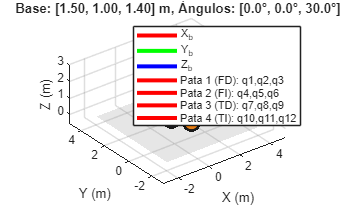


%% Configuración 2: Robot desplazado con rotación yaw
figure(2);
xb2 = 1.5; yb2 = 1.0; zb2 = 1.4;
phi2 = 0; theta2 = 0; psi2 = pi/6;  % 30 grados de yaw
q_legs2 = [
    0.1,   pi/5,  -pi/2.5;  % Pata 1 (FD)
   -0.1,   pi/6,  -pi/2;    % Pata 2 (FI)
    0.15,  pi/4,  -pi/2.2;  % Pata 3 (TD)
   -0.15,  pi/5,  -pi/2.3   % Pata 4 (TI)
];
draw_quadruped(xb2, yb2, zb2, phi2, theta2, psi2, q_legs2, L0, L1, L2, L3, Lc, Lb);

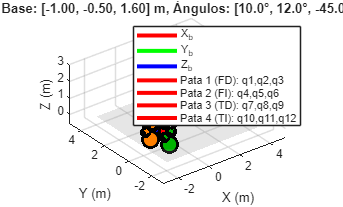


%% Configuración 3: Robot con pitch, roll y yaw
figure(3);
xb3 = -1.0; yb3 = -0.5; zb3 = 1.6;
phi3 = pi/18;   % ~10 grados de roll
theta3 = pi/15; % ~12 grados de pitch
psi3 = -pi/4;   % -45 grados de yaw
q_legs3 = [
    0,     pi/3,  -pi/2;    % Pata 1 (FD)
    0,     pi/6,  -pi/2.5;  % Pata 2 (FI)
    0,     pi/4,  -pi/2.2;  % Pata 3 (TD)
    0,     pi/5,  -pi/2.3   % Pata 4 (TI)
];
draw_quadruped(xb3, yb3, zb3, phi3, theta3, psi3, q_legs3, L0, L1, L2, L3, Lc, Lb);